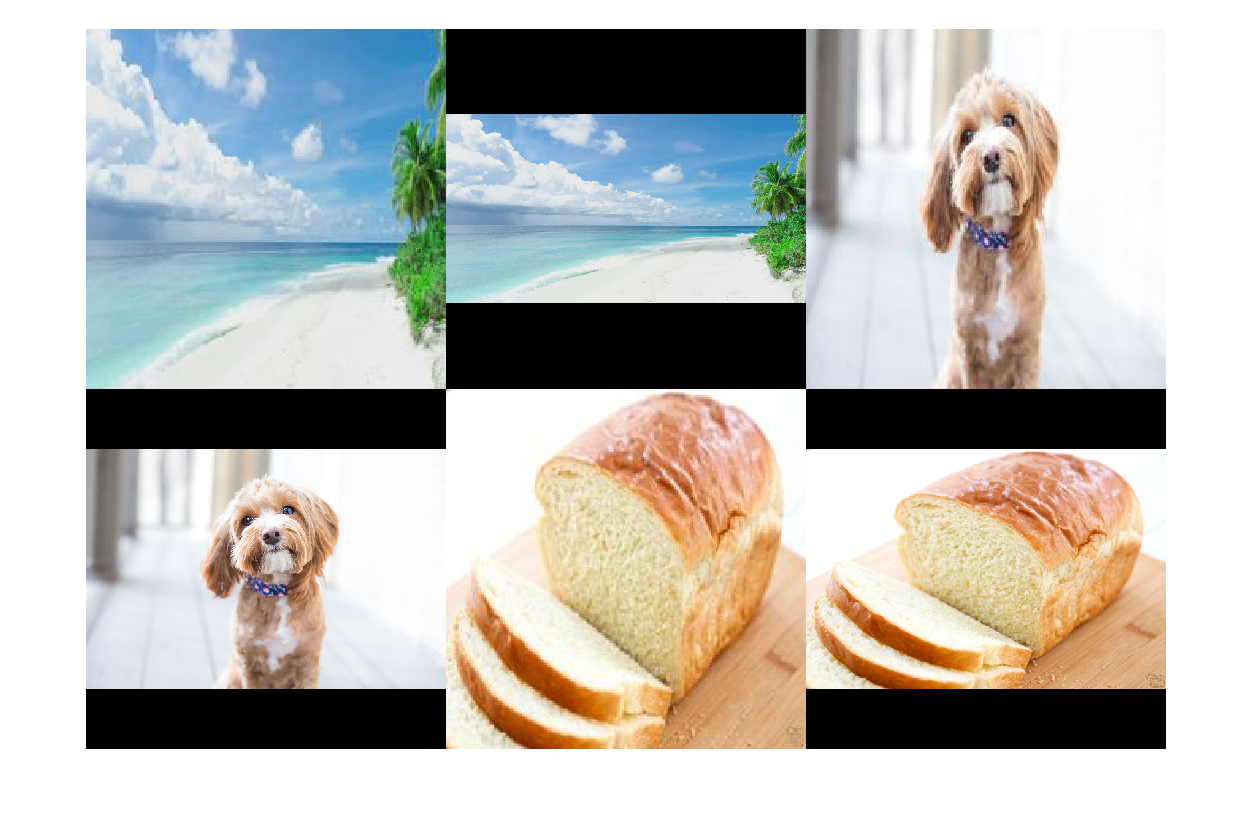

clear; clc; close all;

net = alexnet;

imds = imageDatastore('imgs/*.jpg');
montage(imds);


% RGB => Gray
%auds = augmentedImageDatastore([227, 227], imds, 'ColorPreprocessing', 'rgb2gray');

% Gray => RGB
%auds = augmentedImageDatastore([227, 227], imds, "ColorPreprocessing", "gray2rgb");

% Just resize
auds = augmentedImageDatastore([227, 227], imds);

preds = classify(net, auds);
preds

preds = 6×1 categorical 배열
     seashore 
     seashore 
     Yorkshire terrier 
     Yorkshire terrier 
     French loaf 
     French loaf 
